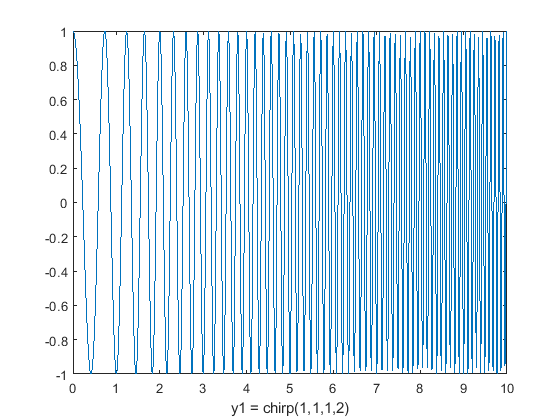

clear all;
dt = 0.01;
pulse_width = 10;
t = 0 : dt : pulse_width; % 0 : dt : 10
N = length(t);
df = (1/dt)/N;  % 대략 0.1
f = 0 : df : (1/dt)-df; % 0 : df : 100

gain1 = 1;
gain2 = 1;
startf1 = 1;
startf2 = 1;
time1 = 1;
time2 = 1;
changef1 = 2;
changef2 = 3;
number = 0;
noiseSD = 1;
%------------------------------------------------------------
% chirp signal
y1 = gain1 * chirp(t, startf1, time1, changef1); 
y2 = gain2 * chirp(t, startf2, time2, changef2);

plot(t,y1)
xlabel('y1 = chirp(1,1,1,2)')

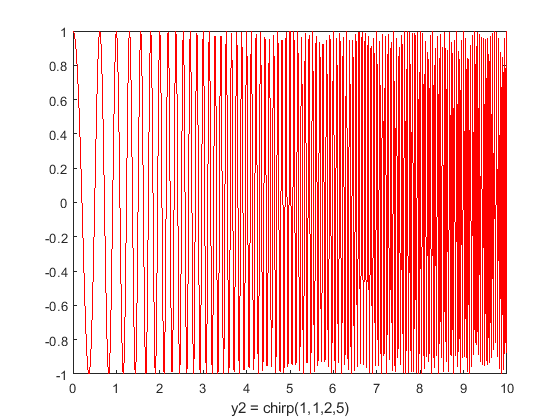


plot(t,y2,'r')
xlabel('y2 = chirp(1,1,2,5)')

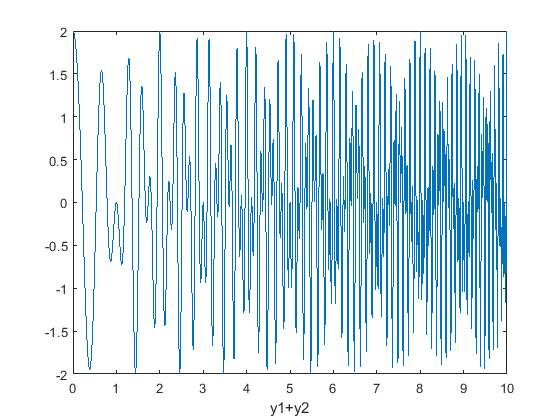


plot(t,y1+y2)
xlabel('y1+y2')

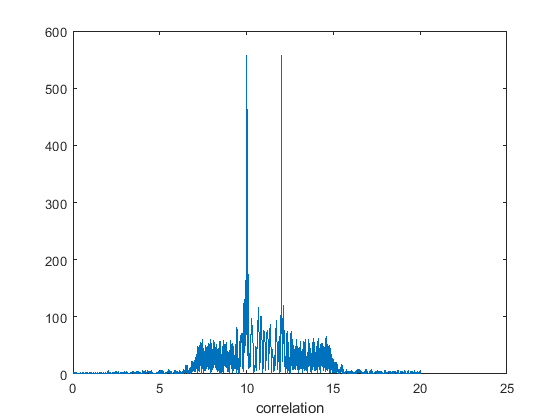


r1 = [ zeros(1,N), y1, zeros(1,N) ];
r2 = [ zeros(1,N+200), y2, zeros(1,N-200) ];
            
r = (r1 + r2) + randn(1,length(r1 + r2))*number*noiseSD;    

% correlation
    ct1 = length(r)-N;
        for a = 0:ct1
            c(a+1) = r(a+1:a+N)*(y1+y2)';
        end

        plot((0:length(c)-1)*dt,abs(c))
        xlabel('correlation')

## rectangular

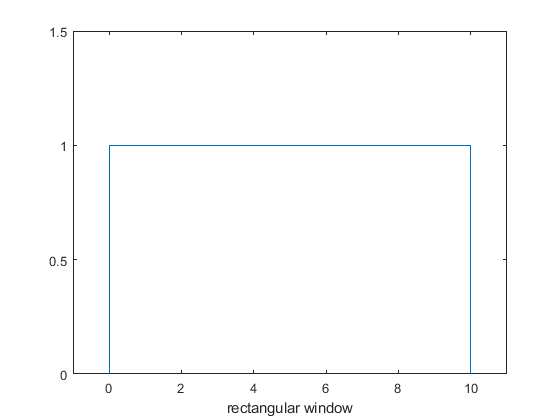

%rectangular

rect=zeros(1,length(t)); %length(c)
for i=1:length(t) %length(t)+N+1
    if t(i) > 0 && t(i) < pulse_width % 0 < t(i) <10
        rect(i) = 1; 
    end
end
plot((0:length(t)-1)*dt,rect)%(0:length(c)-1)*dt
axis([-1 11 0 1.5])
xlabel('rectangular window')

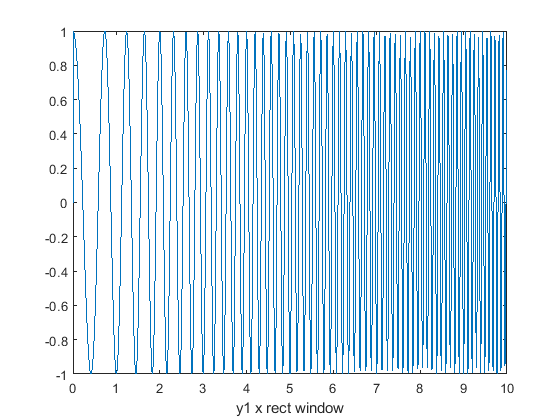


yt1 = y1.*rect;
yt2 = y2.*rect;
yt3 = (y1+y2).*rect;

plot((0:length(t)-1)*dt,(yt1)) %(0:length(c)-1)*dt
xlabel('y1 x rect window')

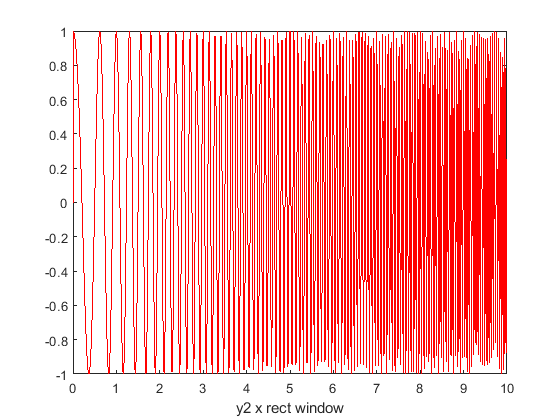


plot((0:length(t)-1)*dt,(yt2),'r')
xlabel('y2 x rect window')

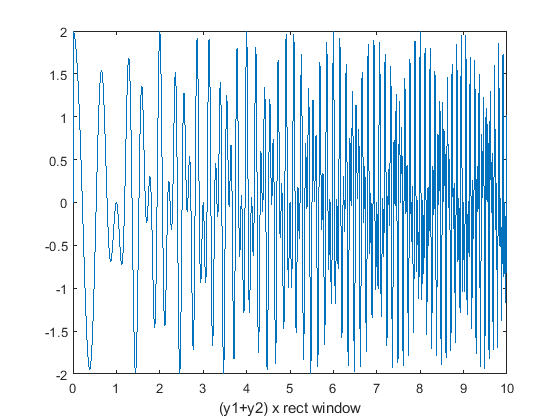


plot((0:length(t)-1)*dt,(yt3))
xlabel('(y1+y2) x rect window')

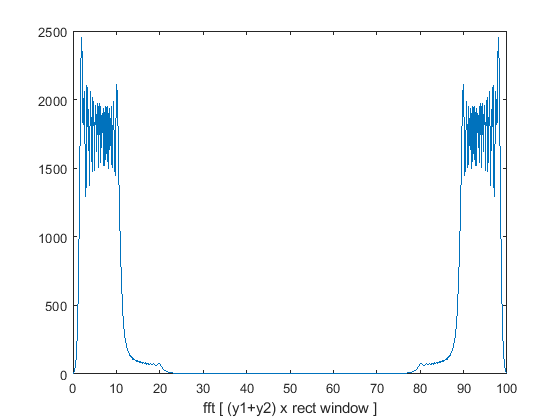


Xt1 = fft(yt1);
Xt2 = fft(yt2);

Xt = Xt1 .* Xt2;
plot((0:length(f)-1)*df,abs(Xt))
xlabel('fft [ (y1+y2) x rect window ]')

## hanning

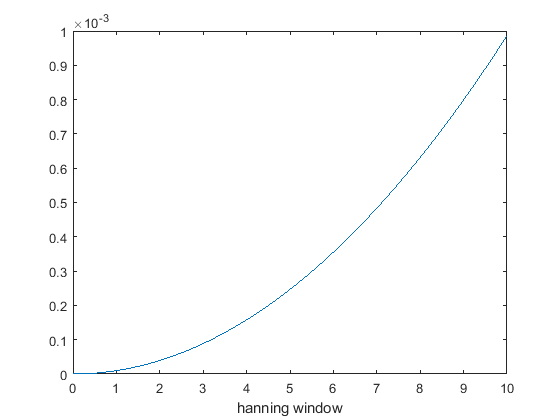

% (0 <= n <= M - 1)
% hanning
% 1/2 .* (1 - cos(2*pi*n/(M-1)))
hanning = 1/2 .* (1 - cos(2*pi*t/(length(t)-1)));
plot(t, hanning)
xlabel('hanning window')

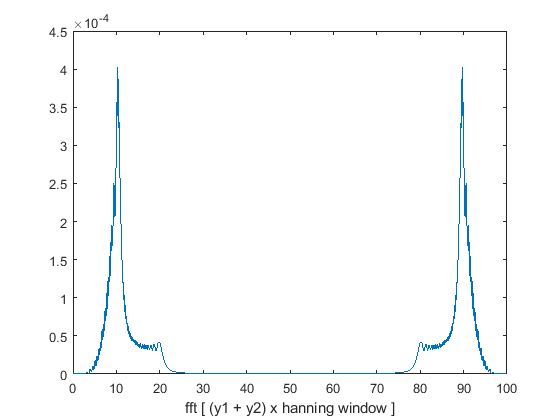


hanning_yt1 = y1 .* 1/2 .* (1 - cos(2*pi*t/(length(t)-1)));
hanning_yt2 = y2 .* 1/2 .* (1 - cos(2*pi*t/(length(t)-1)));

hanning_Xt1 = fft(hanning_yt1);
hanning_Xt2 = fft(hanning_yt2);

hanning_Xt = hanning_Xt1 .* hanning_Xt2;
plot((0:length(f)-1)*df, abs(hanning_Xt))
xlabel('fft [ (y1 + y2) x hanning window ]')

## hamming

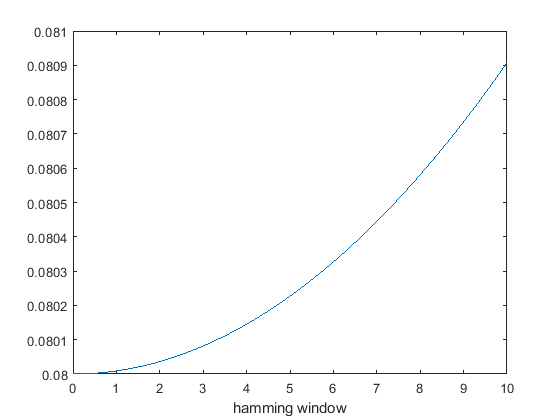

% (0 <= n <= M - 1)
% hamming 수정 필요
% 0.54 - 0.46 * cos(2*pi*n/(M-1))
hamming = 0.54 - 0.46 * cos(2*pi*t/(length(t)-1));
plot(t, hamming)
xlabel('hamming window')

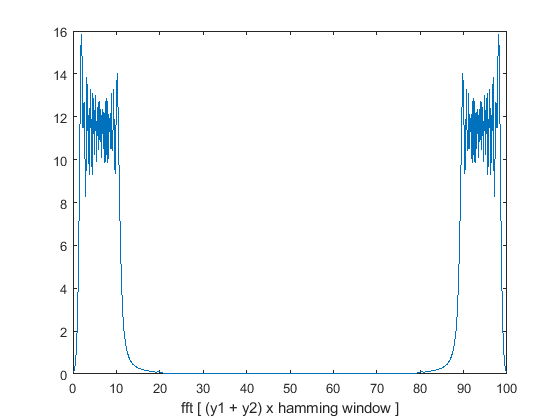


hamming_yt1 = y1 .* (0.54 - 0.46 * cos(2*pi*t/(length(t)-1)));
hamming_yt2 = y2 .* (0.54 - 0.46 * cos(2*pi*t/(length(t)-1)));

hamming_Xt1 = fft(hamming_yt1);
hamming_Xt2 = fft(hamming_yt2);

hamming_Xt = hamming_Xt1 .* hamming_Xt2;
plot((0:length(f)-1)*df, abs(hamming_Xt))
xlabel('fft [ (y1 + y2) x hamming window ]')

## blackman

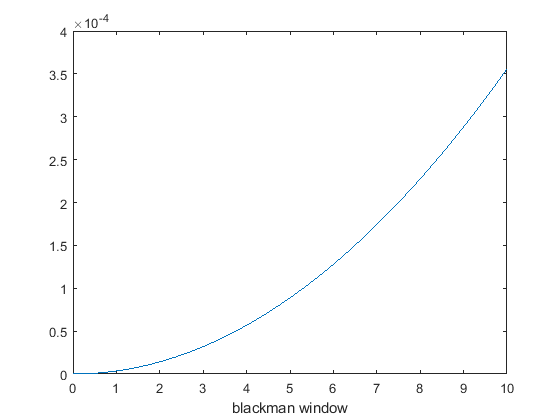

% (0 <= n <= M - 1)
% blackman 수정필요
% 0.42 - 0.5 * cos(2*pi*n/(M-1)) + 0.08 * cos(4*pi*n/(M-1))
blackman = 0.42 - 0.5 * cos(2*pi*t/(length(t)-1)) + 0.08 * cos(4*pi*t/(length(t)-1));
plot(t, blackman)
xlabel('blackman window')

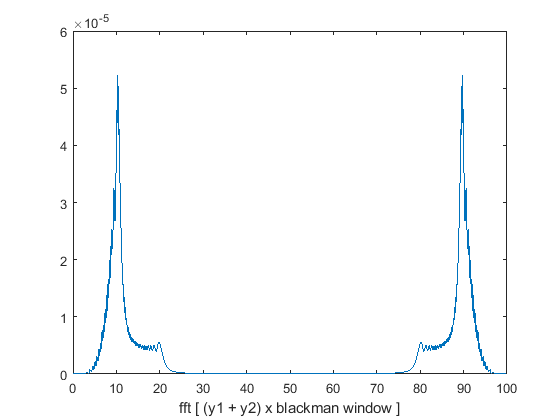


blackman_yt1 = y1 .* (0.42 - (0.5 .* cos(2*pi*t/(length(t)-1))) + (0.08 .* cos(4*pi*t/(length(t)-1))));
blackman_yt2 = y2 .* (0.42 - (0.5 .* cos(2*pi*t/(length(t)-1))) + (0.08 .* cos(4*pi*t/(length(t)-1))));

blackman_Xt1 = fft(blackman_yt1);
blackman_Xt2 = fft(blackman_yt2);

blackman_Xt = blackman_Xt1 .* blackman_Xt2;
plot((0:length(f)-1)*df, abs(blackman_Xt))
xlabel('fft [ (y1 + y2) x blackman window ]')

## kaiser

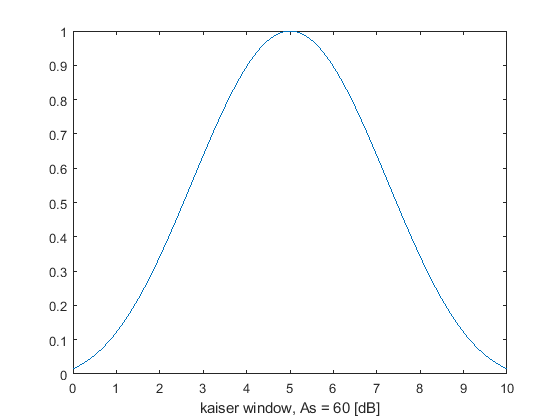

% (0 <= n <= M - 1)
% kaiser
% i0*[ (alpa * sqrt({(M-1)/2)}^2 - {n - (M-1)/2)}^2) ) ] / i0*[(alpa * {(M-1)/2)}^2)]
As = 60; % 60[dB]
beta = 0.1102*(As-8.7) + 0.3; % As >= 50
% beta = 0.5842*(As-21)^0.4 + 0.07886*(As-21) % 21 < As < 50 

kai = (kaiser(length(t),beta))';
plot(t,kai)
xlabel('kaiser window, As = 60 [dB]')

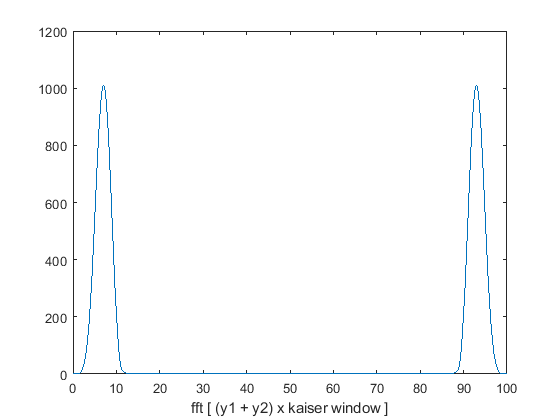


kaiser_yt1 = y1 .* kai;
kaiser_yt2 = y2 .* kai;

kaiser_Xt1 = fft(kaiser_yt1);
kaiser_Xt2 = fft(kaiser_yt2);

kaiser_Xt = kaiser_Xt1 .* kaiser_Xt2;
plot((0:length(f)-1)*df, abs(kaiser_Xt))
xlabel('fft [ (y1 + y2) x kaiser window ]')